%% CÁLCULO DE ALPHA Y R (Con corrección de sustrato/vidrio)
clear; clc; close all;

%% 1. CONFIGURACIÓN Y CARGA DE ARCHIVOS
% ---------------------------------------------------------
% Nombres de tus archivos .asc
file_T_meas = 'C-200W-5Ar_T.Sample.asc';   % Transmitancia medida de la muestra
file_R_meas = 'C-200W-5Ar.Sample.asc';   % Reflectancia medida de la muestra
file_T_vidrio = 'Vidrio.Sample.asc';  % Transmitancia del sustrato (Vidrio)
    
d = 20.362^(-7); % Espesor de la capa (film) en cm
% ---------------------------------------------------------

% Leemos los tres archivos usando la función auxiliar
[lam_Tm, Tm_data] = leer_perkin_elmer(file_T_meas);
[lam_Rm, Rm_data] = leer_perkin_elmer(file_R_meas);
[lam_Tv, Tv_data] = leer_perkin_elmer(file_T_vidrio);

%% 2. PRE-PROCESAMIENTO Y SINCRONIZACIÓN
% Buscamos el rango de longitud de onda común a los 3 archivos
min_lam = max([min(lam_Tm), min(lam_Rm), min(lam_Tv)]);
max_lam = min([max(lam_Tm), max(lam_Rm), max(lam_Tv)]);

% Vector común de longitudes de onda (paso de 1 nm)
lambda = (max_lam:-1:min_lam)'; 

% Interpolamos todos los datos a este vector común
Tm_interp = interp1(lam_Tm, Tm_data, lambda, 'pchip');
Rm_interp = interp1(lam_Rm, Rm_data, lambda, 'pchip');
Tv_interp = interp1(lam_Tv, Tv_data, lambda, 'pchip');

% --- PASO CRÍTICO: Conversión y Normalización ---

% 1. Convertir todo de Porcentaje (0-100) a Tanto por uno (0-1)
Tm_val = Tm_interp / 100;
Rm_val = Rm_interp / 100;
Tv_val = Tv_interp / 100;

% 2. Corrección por el sustrato: T_input = T_medida / T_vidrio
% Evitamos división por cero por seguridad
Tv_val(Tv_val == 0) = NaN; 

T_input = Tm_val ./ Tv_val;

% Limpieza: Si por ruido T_input > 1, lo acotamos a 1 (físicamente imposible >1 sin ganancia)
T_input(T_input > 1) = 0.9999; 

% La Reflectancia NO se suele dividir por el vidrio en este modelo simple,
% se usa la medida directa del conjunto o se requiere un modelo más complejo.
% Usaremos la medida directa como R input.
R_input = Rm_val; 

%% 3. BUCLE DE CÁLCULO (Solver)
n_puntos = length(lambda);
alpha_calc = zeros(n_puntos, 1);
R_film_calc = zeros(n_puntos, 1);

% Estimación inicial (Initial Guess)
x0 = [10000, 0.1]; 

options = optimoptions('fsolve', 'Display', 'off', ...
    'FunctionTolerance', 1e-10, 'OptimalityTolerance', 1e-10);

wb = waitbar(0, 'Iniciando cálculo...');

for i = 1:n_puntos
    if mod(i,10)==0; waitbar(i/n_puntos, wb, sprintf('Lambda: %.0f nm', lambda(i))); end
    
    T_target = T_input(i);
    R_target = R_input(i);
    
    % Si hay NaNs (por división por cero o datos faltantes), saltamos
    if isnan(T_target) || isnan(R_target)
        alpha_calc(i) = NaN;
        R_film_calc(i) = NaN;
        continue;
    end
    
    sistema = @(x) ecuaciones_opticas(x, T_target, R_target, d);
    
    [sol, ~, exitflag] = fsolve(sistema, x0, options);
    
    if exitflag > 0 && isreal(sol)
        % Filtro físico: Alpha no debe ser negativo
        if sol(1) < 0; sol(1) = 0; end
        
        alpha_calc(i) = sol(1);
        R_film_calc(i) = sol(2);
        x0 = sol; % Actualizamos semilla
    else
        alpha_calc(i) = NaN;
        R_film_calc(i) = NaN;
        x0 = [10000, 0.1]; % Reset semilla
    end
end
close(wb);

     %% 5. EXPORTACIÓN DE RESULTADOS (NUEVO)
    nombre_archivo = 'Resultados_Alpha_R.txt';
    fprintf('Guardando datos en: %s ...\n', nombre_archivo);

Guardando datos en: Resultados_Alpha_R.txt ...


    
    % Abrimos el archivo para escritura ('w')
    fid = fopen(nombre_archivo, 'w');
    
    % Escribimos el encabezado (Header)
    % \t significa "tabulación", \n significa "nueva línea"
    fprintf(fid, 'Longitud_Onda(nm)\tAlpha(cm^-1)\tReflectividad(R)\n');
    
    % Preparamos una matriz temporal para escribir todo de una vez
    % Transponemos (') la matriz porque fprintf lee por columnas
    matriz_datos = [lambda, alpha_calc, R_film_calc]';
    
    % Escribimos los datos
    % %.2f = 2 decimales, %.6f = 6 decimales
    fprintf(fid, '%.2f\t%.6f\t%.6f\n', matriz_datos);
    
    % Cerramos el archivo
    fclose(fid);
    
    fprintf('¡Archivo guardado con éxito!\n');

¡Archivo guardado con éxito!


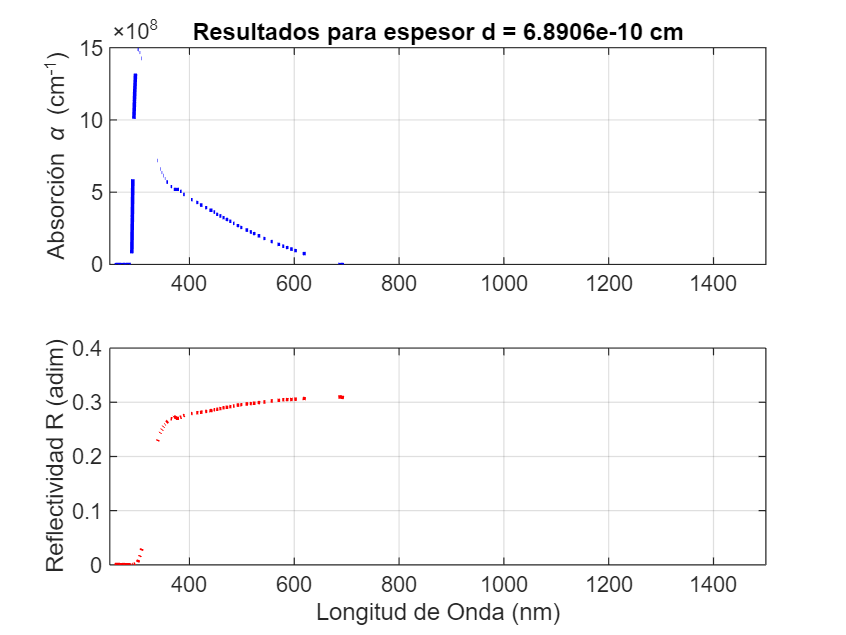


%% 4. GRAFICAR RESULTADOS
figure('Color','w', 'Position', [100 100 800 600]);

subplot(2,1,1);
plot(lambda, alpha_calc, 'b-', 'LineWidth', 1.5);
ylabel('Absorción \alpha (cm^{-1})');
title(['Resultados para espesor d = ' num2str(d) ' cm']);
grid on; xlim([min(lambda) max(lambda)]);

subplot(2,1,2);
plot(lambda, R_film_calc, 'r-', 'LineWidth', 1.5);
xlabel('Longitud de Onda (nm)');
ylabel('Reflectividad R (adim)');
grid on; xlim([min(lambda) max(lambda)]);

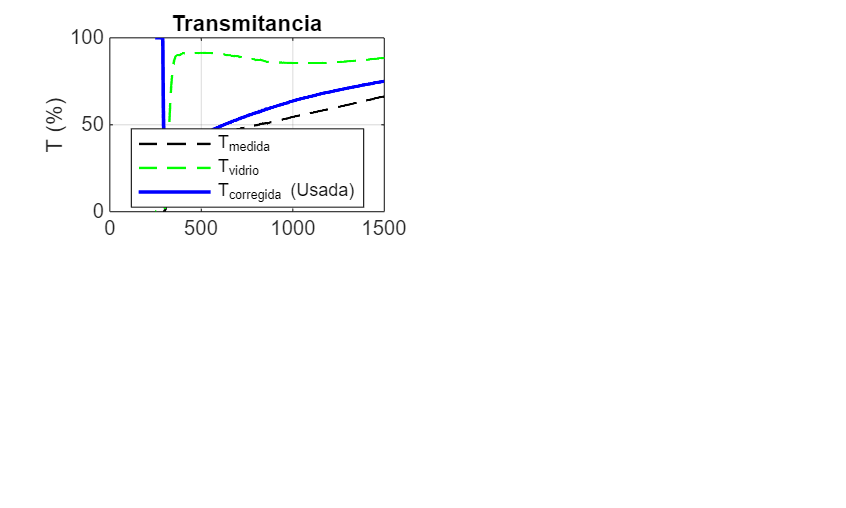



%% --- FUNCIONES AUXILIARES ---
% (Deben ir al final del script)


%% 4. GRAFICAR RESULTADOS
figure('Color','w', 'Position', [50 50 1000 600]);

subplot(2,2,1);
plot(lambda, Tm_val*100, 'k--', 'LineWidth', 1); hold on;
plot(lambda, Tv_val*100, 'g--', 'LineWidth', 1);
plot(lambda, T_input*100, 'b-', 'LineWidth', 1.5);
title('Transmitancia');
legend('T_{medida}', 'T_{vidrio}', 'T_{corregida} (Usada)', 'Location','best');
ylabel('T (%)'); grid on; 


function [lambda, valores] = leer_perkin_elmer(filename)
    % Esta función lee el formato específico PE .asc con comas
    if ~isfile(filename)
        error('No se encuentra el archivo: %s. Asegúrate de que está en la carpeta.', filename);
    end
    
    fid = fopen(filename, 'r');
    
    % 1. Buscar dónde empiezan los datos
    encontrado = false;
    while ~feof(fid)
        linea = fgetl(fid);
        if contains(linea, '#DATA')
            encontrado = true;
            break;
        end
    end
    
    if ~encontrado
        fclose(fid);
        error('El archivo %s no tiene la etiqueta #DATA.', filename);
    end
    
    % 2. Leer columnas
    datos_raw = textscan(fid, '%s %s');
    fclose(fid);
    
    col_lambda_str = datos_raw{1};
    col_valor_str = datos_raw{2};
    
    % 3. Reemplazar comas por puntos y convertir
    col_lambda_str = strrep(col_lambda_str, ',', '.');
    col_valor_str = strrep(col_valor_str, ',', '.');
    
    lambda = str2double(col_lambda_str);
    valores = str2double(col_valor_str);
end

function F = ecuaciones_opticas(x, Tm, Rm, d)
    % x(1) = alpha, x(2) = R
    alpha = x(1);
    R = x(2);
    
    % Restricción suave para evitar inestabilidad numérica
    if R >= 1; R = 0.9999; end
    
    E = exp(-alpha * d);
    E2 = exp(-2 * alpha * d);
    denom2 = 1 - (R^2 * E2);
    
    T_teorico = ((1-R)^2 * E) / denom2;
    R_teorico = R + (R * (1-R)^2 * E2) / denom2;
    
    F = [Tm - T_teorico;
         Rm - R_teorico];
end
